addpath('D:\matlabfiles\CourseMaterial\CourseMaterial\Code\functions')
addpath('D:\matlabfiles\CourseMaterial\CourseMaterial\Code\data')
addpath('D:\matlabfiles\CourseMaterial\CourseMaterial\Code\yxx\')

clear; clc;
close all;
load projectData24.mat
load group049\Mbj.mat
load group049\m1im.mat


k       = 18;                                            % Prediction horizon.
groupNo = 49;                                            % Example group number.
nolags  = 200;
sweek   = 168;
sday    = 24;                                           % Daily season.

grpStr = num2str( groupNo );
switch length(grpStr)
    case 1       
        grpStr = append("00", grpStr); 
    case 2       
        grpStr = append("0", grpStr); 
end
grpStr = append("group", grpStr);
addpath('../functions', '../data', grpStr)              % Sets the path to your code.


InputInd=data(:,6);
DataInd=data(:,8);
Data=DataInd(1:50000);
DataTestInd=50001:60624;
DataTest=DataInd(50001:end);                          % Leave some data to test the predictor
Input=InputInd(1:50000);
InputTest=InputInd(DataTestInd);
A24=[1 zeros(1,23) -1];

trainDataInd = 30025:30024+sweek*8;                     % Select some training data; these 8 weeks seems nice.
trainingData = Data(trainDataInd);                      % Notice that the model is build on only the training data.
trainingInput = Input(trainDataInd);

%Part C: Kalman filter
%make the polynomial prediction first
ud=filter(A24,[1],InputInd);
yd=filter(A24,[1],DataInd);

for i=1:k
    [Fkx, Gkx] = polydivision( m1im.C, m1im.A, i );
    uhatk (:,i)= filter(Gkx, m1im.C, ud);
end
KA = conv( Mbj.D, Mbj.F );
KB = conv( Mbj.D, Mbj.B );
KC = conv( Mbj.F, Mbj.C );
[Fy, Gy]   = polydivision( Mbj.C, Mbj.D, k );
[Fhh, Ghh] = polydivision( conv(Fy, KB), KC, k );
yhatP = filter(Fhh, 1, uhatk(:,1)) + filter(Ghh, KC, ud) + filter(Gy, KC, DataInd);
eP    = DataInd(50001:end)-yhatP(50001:end);    % Form the prediction residuals for the validation data.

%Estimate the unknown parameters using a Kalman filter and form the one-step prediction.
%we predict the input and output in one loop.
nopar=16;
N=length(DataInd);
k=18;
Rxx_1=eye(2);
RRxx_1=eye(16);
xt_t1=[-0.7464 -0.7882]';
xxt_t1=[-1.7149 0.3816 0.4816 -0.1467 0.0059 -0.006 -0.0021 0.0021 -0.0013 0.002 -0.0006 -0.4689 -0.4975 -0.8364 0.3922 0.4161]';
Xsave=zeros(2,N);
XXsave=zeros(16,N);
ehat=zeros(1,N);
ehat2=zeros(1,N);
uhat=zeros(1,N);
yhat=zeros(1,N);
ut=zeros(k,N);
yt=zeros(k,N);
A=eye(2);
Rw=200;
RRw=200;
% Re=10e-6*eye(2);
Re=10e-6*eye(2);
RRe=10e-6*eye(16);
for t=2:N-k
    if t>24
       Ct=[-ud(t-1) -ehat(t-24)];
       if t>26
          CCt=[-yd(t-1) -yd(t-2) -yd(t-3) -yd(t-4) ud(t) ud(t-1) ud(t-2) ud(t-3) ud(t-4) ud(t-5) ud(t-6) ehat2(t-1) ehat2(t-2) ehat2(t-24) ehat2(t-25) ehat2(t-26)];
       else
          CCt=[-yd(t-1) -yd(t-2) -yd(t-3) -yd(t-4) ud(t) ud(t-1) ud(t-2) ud(t-3) ud(t-4) ud(t-5) ud(t-6) ehat2(t-1) ehat2(t-2) 0 0 0];
       end
    else
       Ct=[-ud(t-1) 0];
       CCt=[-yd(t-1) 0 0 0 ud(t) ud(t-1) 0 0 0 0 0 ehat2(t-1) 0 0 0 0];
    end
    uhat(t)=Ct*xt_t1;
    yhat(t)=CCt*xxt_t1;
    ehat(t)=ud(t)-uhat(t);
    ehat2(t)=yd(t)-yhat(t);
    Ryy=Ct*Rxx_1*Ct'+Rw;
    RRyy=CCt*RRxx_1*CCt'+RRw;
    Kt=Rxx_1*Ct'/Ryy;
    KKt=RRxx_1*CCt'/RRyy;
    xt_t=xt_t1+Kt*(ehat(t));
    xxt_t=xxt_t1+KKt*(ehat2(t));
    Rxx=Rxx_1-Kt*Ryy*Kt';
    RRxx=RRxx_1-KKt*RRyy*KKt';
    xt_t1=A*xt_t;
    xxt_t1=xxt_t;
    Rxx_1=A*Rxx*A'+Re;
    RRxx_1=RRxx+RRe;
    if t>25
        Ctt=zeros(k,2);
        Ctt(1,:)=[-ud(t) ehat(t-23)];
        ut(1,t+1)=Ctt(1,:)*xt_t;
        for i=2:k
            Ctt(i,:)=[-ut(i-1,t+i-1) ehat(t-24+i)];
            ut(i,t+i)=Ctt(i,:)*xt_t;
        end
        udd=ud;
        udd(t+1)=ut(1,t+1);
        ydd=yd;
        eehat2=ehat2;
        eehat2(t+1:t+k)=zeros(1,k);
        CCtt=zeros(k,16);
        CCtt(1,:)=[-yd(t) -yd(t-1) -yd(t-2) -yd(t-3) udd(t+1) ud(t) ud(t-1) ud(t-2) ud(t-3) ud(t-4) ud(t-5) ehat2(t) ehat2(t-1) ehat2(t-23) ehat2(t-24) ehat2(t-25)];
        yt(1,t+1)=CCtt(1,:)*xxt_t;
        for i=2:k
            udd(t+i)=ut(i-1,t+i);
            ydd(t+i-1)=yt(i-1,t+i-1);
            CCtt(i,:)=[-ydd(t+i-1) -ydd(t+i-2) -ydd(t+i-3) -ydd(t+i-4) udd(t+i) udd(t+i-1) udd(t+i-2) udd(t+i-3) udd(t+i-4) udd(t+i-5) udd(t+i-6) eehat2(t+i-1) eehat2(t+i-2) eehat2(t+i-24) eehat2(t+i-25) eehat2(t+i-26)];
            yt(i,t+i)=CCtt(i,:)*xxt_t;
        end

    end
    Xsave(:,t)=xt_t;
    XXsave(:,t)=xxt_t;
end
yhat=yt';
for i=1:24
    yhat(i,:)=yt(:,i)';
end
for i=25:N
    yhat(i,:)=yt(:,i)'+DataInd(i-24);
end

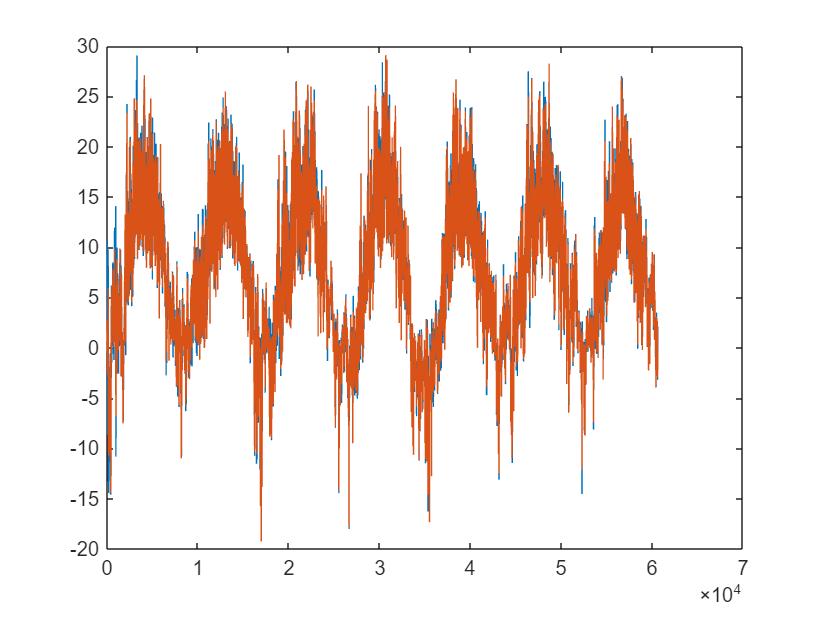

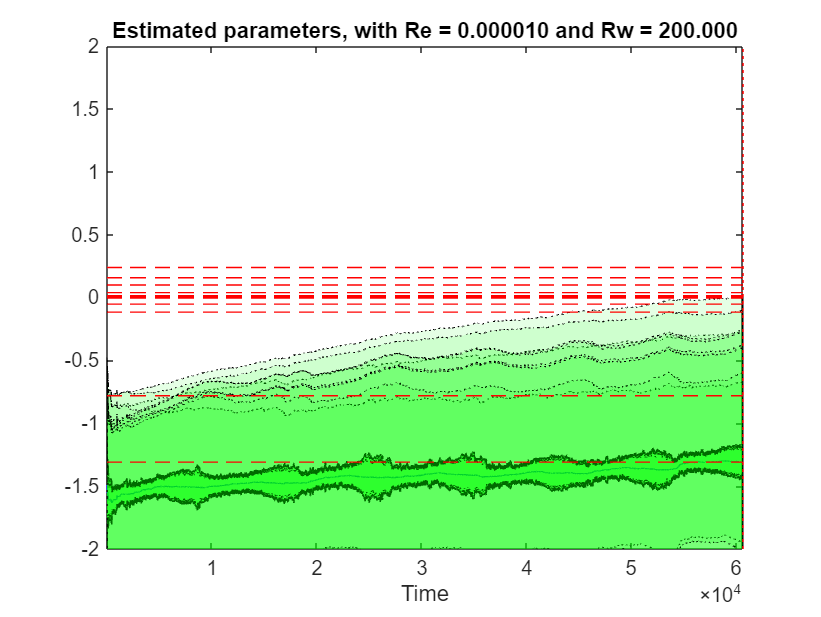

%seems to work.
plot(1:60624,yhat(:,3))
hold on
plot(1:60624,DataInd)
hold off

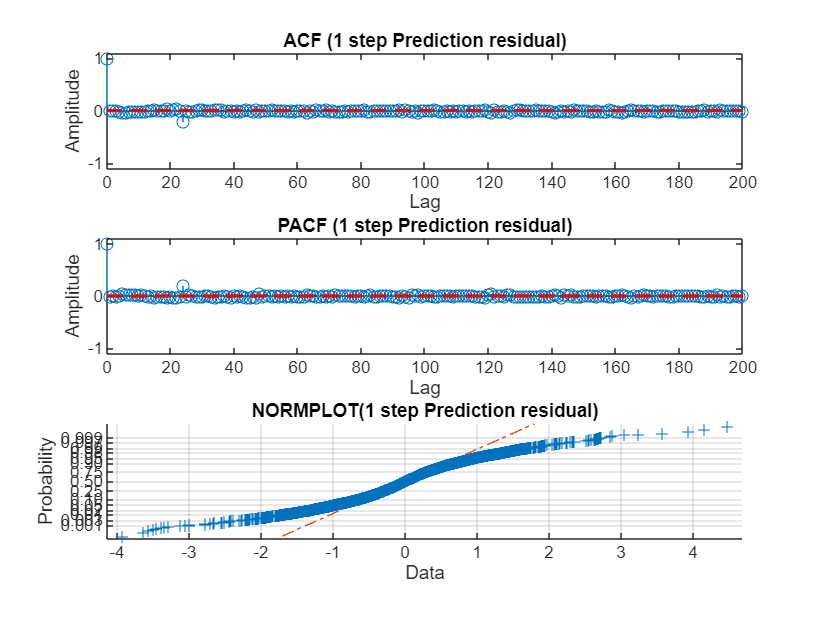


% now test the prediction
yhat1=yhat(DataTestInd,1);
ehatA_P1 = DataTest-yhat1;
var_predA_1a = var( ehatA_P1 );

ynaive=filter([zeros(1,1) 1],[1],DataInd);
ynaive=ynaive(DataTestInd);
ehatnaive = DataTest-ynaive;
var_naive=var( ehatnaive );

[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '1 step Prediction residual');

varY = var( DataTest );
fprintf('Prediction results for the 1-step prediction:\n')

Prediction results for the 1-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is     37.62


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is    0.36. The normalized variance is 0.0097.


fprintf('  The variance of the naive predictor is %7.2f. The normalized variance is %5.4f.\n', var_naive, var_naive/varY )

  The variance of the naive predictor is    0.44. The normalized variance is 0.0118.


checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 83.06 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


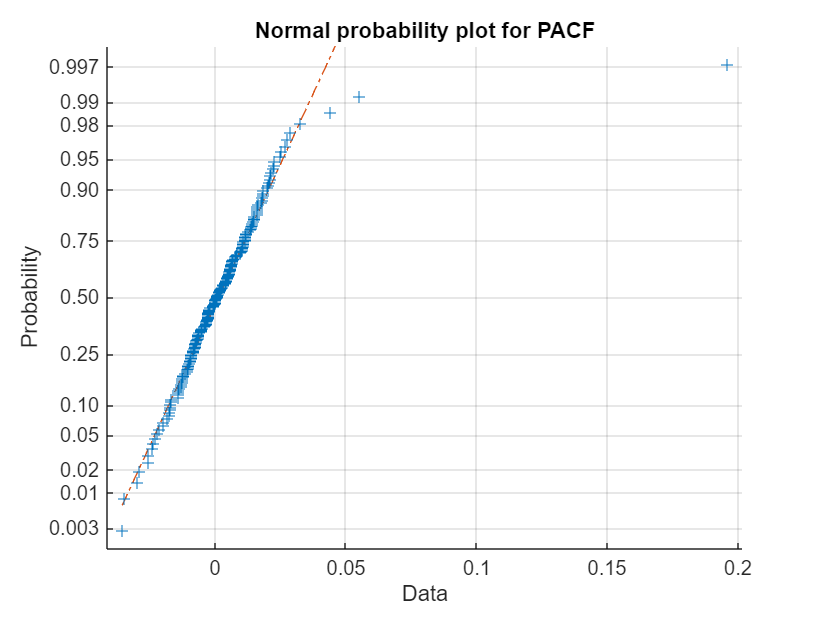

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );

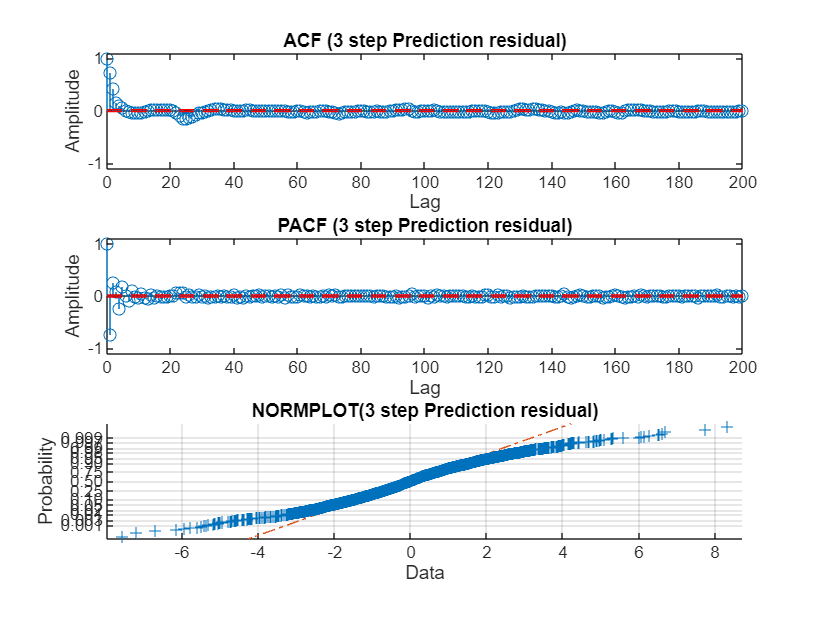


yhat3=yhat(DataTestInd,3);
ehatA_P1 = DataTest-yhat3;
var_predA_1a = var( ehatA_P1 );

ynaive=filter([zeros(1,3) 1],[1],DataInd);
ynaive=ynaive(DataTestInd);
ehatnaive = DataTest-ynaive;
var_naive=var( ehatnaive );

[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '3 step Prediction residual');

varY = var( DataTest );
fprintf('Prediction results for the 3-step prediction:\n')

Prediction results for the 3-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is     37.62


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is    1.63. The normalized variance is 0.0432.


fprintf('  The variance of the naive predictor is %7.2f. The normalized variance is %5.4f.\n', var_naive, var_naive/varY )

  The variance of the naive predictor is    2.72. The normalized variance is 0.0722.


checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 7814.78 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


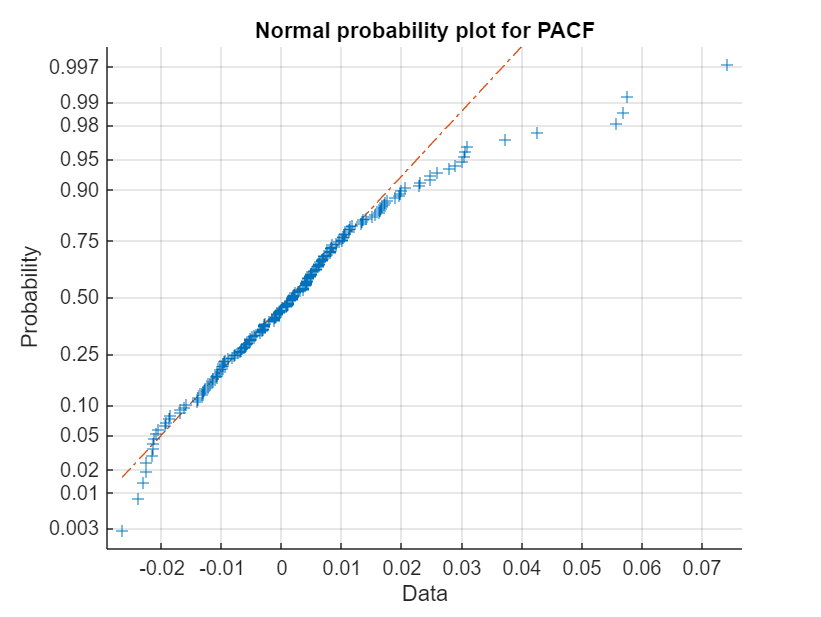

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );

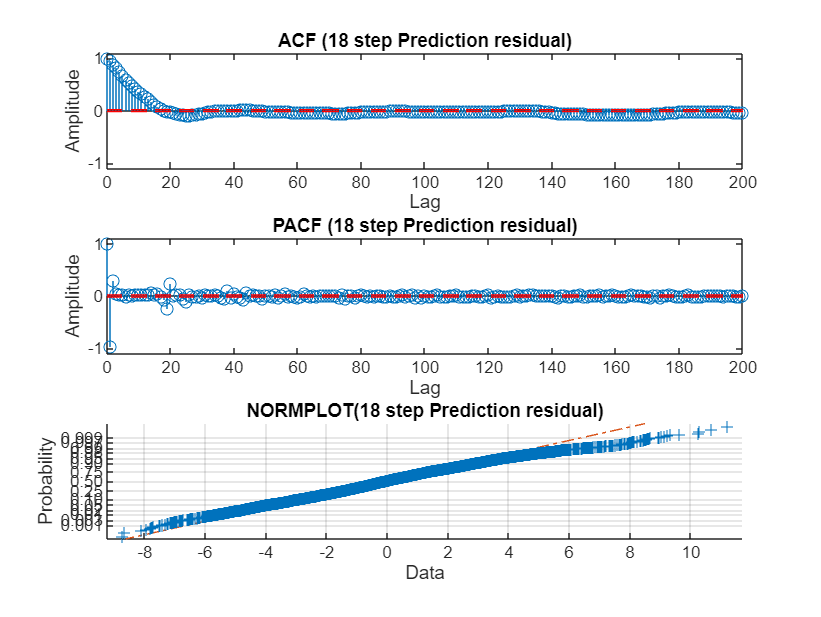


yhat18=yhat(DataTestInd,18);
ehatA_P1 = DataTest-yhat18;
var_predA_1a = var( ehatA_P1 );

ynaive=filter([zeros(1,24) 1],[1],DataInd);
ynaive=ynaive(DataTestInd);
ehatnaive = DataTest-ynaive;
var_naive=var( ehatnaive );

[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '18 step Prediction residual');

varY = var( DataTest );
fprintf('Prediction results for the 18-step prediction:\n')

Prediction results for the 18-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is     37.62


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is    5.57. The normalized variance is 0.1481.


fprintf('  The variance of the naive predictor is %7.2f. The normalized variance is %5.4f.\n', var_naive, var_naive/varY )

  The variance of the naive predictor is    6.05. The normalized variance is 0.1608.


checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 12056.99 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


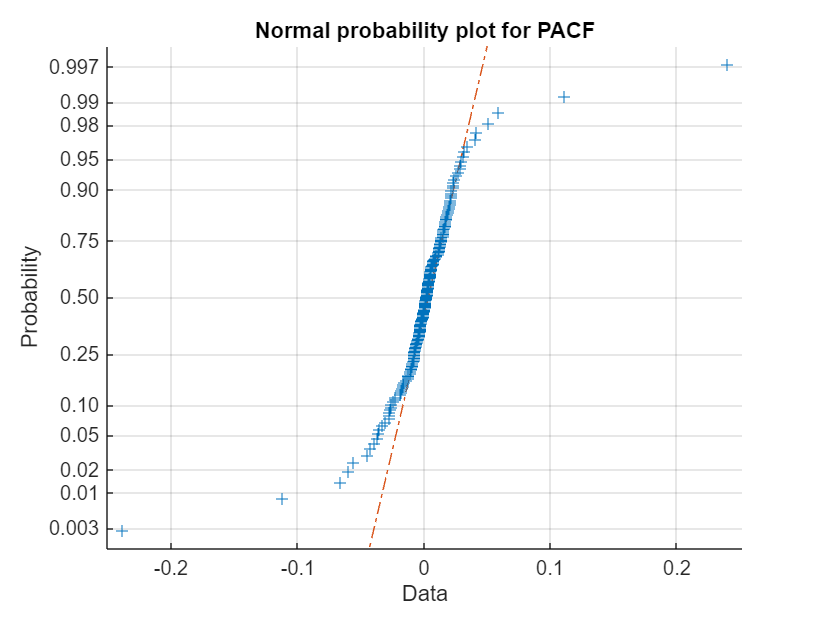

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );